# SNS Lab 08

## Syed Muhammad Asad Ali

### sa09475

#### Task 1 (Post lab)

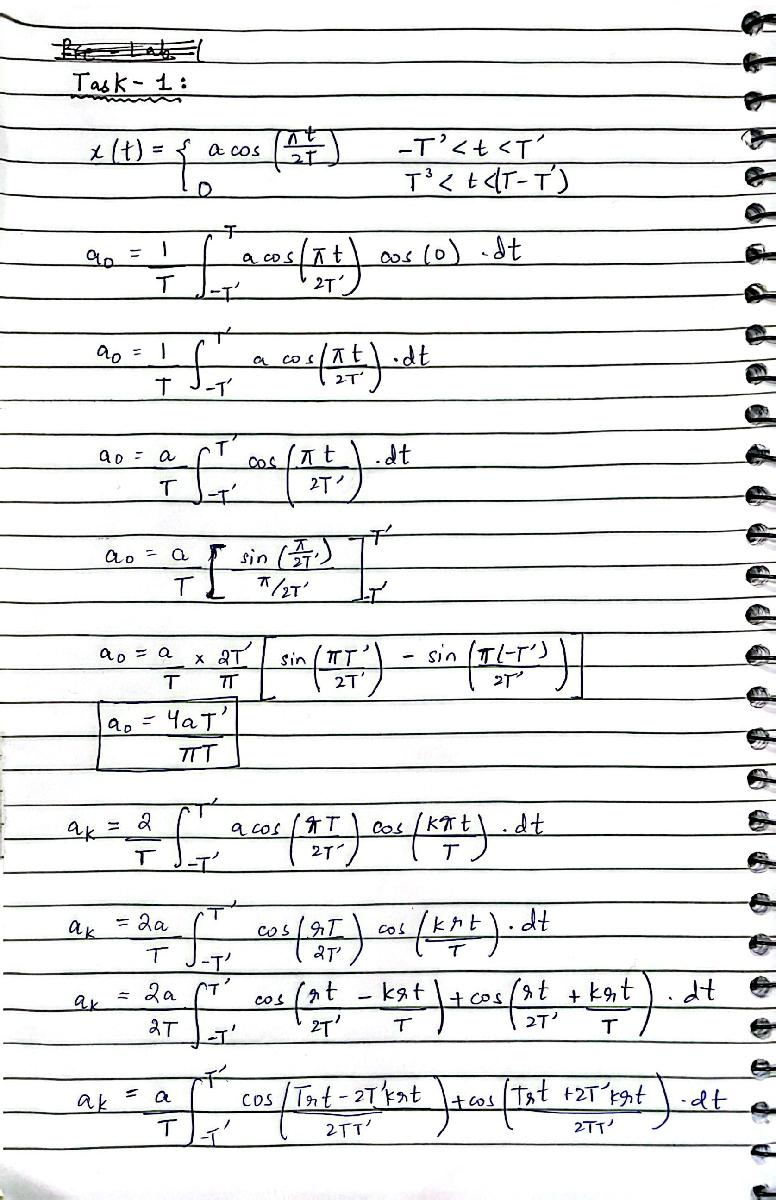

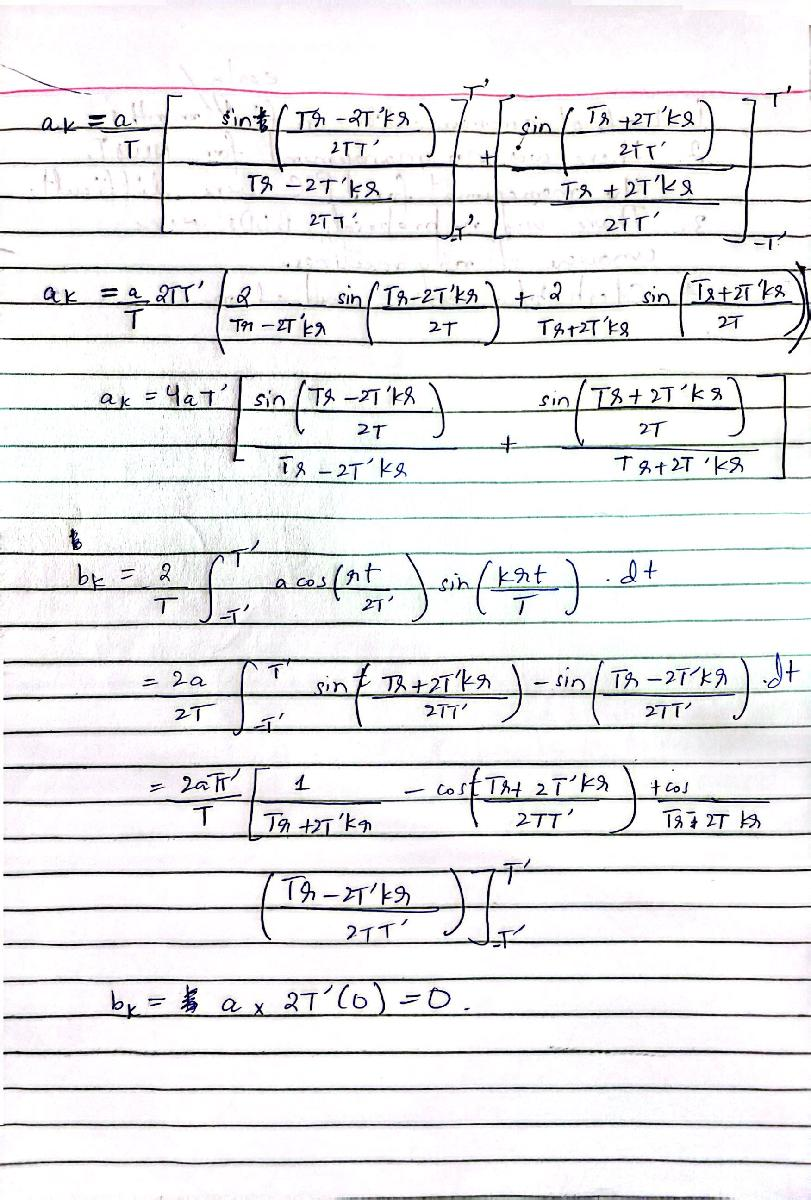

### Task 2

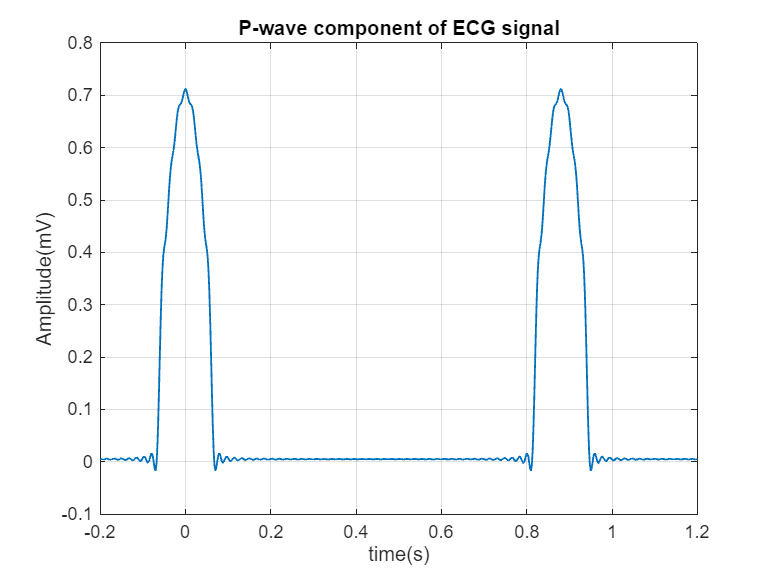

%parameters
N=50;
a=0.35;
T=0.88;
Td=0.16;
t=-0.2:1/N/10:1.2;
k=1:N;

% Calculating a0 and ak 
a0=(4*a*Td)/(pi*T); 
ak=4*a*Td*((sin((pi*T-2*k*pi*Td)./2*T)./(pi*T-2*k*pi*Td))+(sin((pi*T+2*k*pi*Td)./2*T)./(pi*T+2*k*pi*Td)));

% Initializing xtNp with a0
bk=0;
xtNp=a0;

% Sum to compute xtNp
for kk=1:N
   xtNp=xtNp + ak(kk)*cos((2*kk*pi*t)/T);
end

% Ploting the P-wave component of ECG signal
figure;
plot(t, xtNp, 'linewidth', 1);
grid on;
xlabel('time(s)');
ylabel('Amplitude(mV)');
title('P-wave component of ECG signal');

#### Task 3

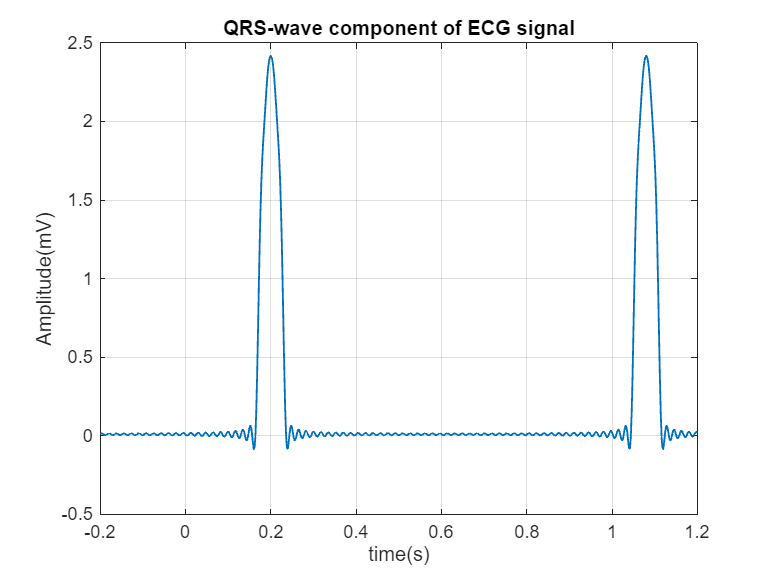

%parameters
N=50;
a=1.2;
T=0.88;
Td=0.08;
t0=0.2;
t=-0.2:1/N/10:1.2;
k=1:N;

% Calculating a0 and ak
a0 = (4*a*Td)/(pi*T);
ak=4*a*Td*((sin((pi*T-2*k*pi*Td)./2*T)./(pi*T-2*k*pi*Td))+(sin((pi*T+2*k*pi*Td)./2*T)./(pi*T+2*k*pi*Td)));

% Initializing xtNp with a0
bk=0;
xtNq = a0;

% Sum to compute xtNp
for kk=1:N
   xtNq = xtNq+ak(kk)*cos((2*kk*pi*(t-t0)/T));
end

% Ploting the QRS-wave component of ECG signal
figure;
plot(t, xtNq, 'linewidth',1);
grid on; xlabel('time(s)');
ylabel('Amplitude(mV)')
title('QRS-wave component of ECG signal');

#### Task 4

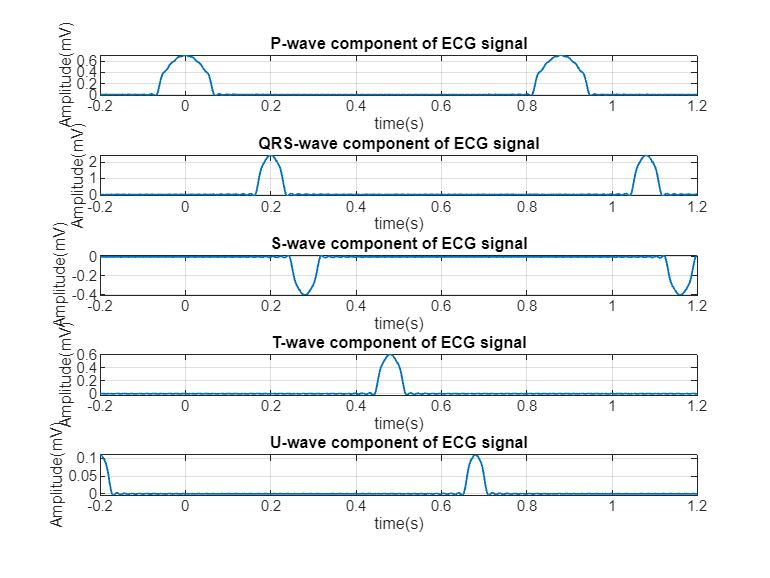

%parameters Plot of P
N=50;
a=0.35;
T=0.88;
Td=0.16;
t=-0.2:1/N/10:1.2;
k=1:N;

% Calculating a0 and ak 
a0=(4*a*Td)/(pi*T); 
ak=4*a*Td*((sin((pi*T-2*k*pi*Td)./2*T)./(pi*T-2*k*pi*Td))+(sin((pi*T+2*k*pi*Td)./2*T)./(pi*T+2*k*pi*Td)));

% Initializing xtNp with a0
xtNp=a0;

% Sum to compute xtNp
for kk=1:N
   xtNp=xtNp + ak(kk)*cos((2*kk*pi*t)/T);
end

% Ploting the P-wave component of ECG signal
subplot(5,1,1)
plot(t, xtNp, 'linewidth', 1);
grid on;
xlabel('time(s)');
ylabel('Amplitude(mV)');
title('P-wave component of ECG signal');

%parameters plot of QRS
N=50;
a=1.2;
T=0.88;
Td=0.08;
t0=0.2;
t=-0.2:1/N/10:1.2;
k=1:N;

% Calculating a0 and ak
a0 = (4*a*Td)/(pi*T);
ak=4*a*Td*((sin((pi*T-2*k*pi*Td)./2*T)./(pi*T-2*k*pi*Td))+(sin((pi*T+2*k*pi*Td)./2*T)./(pi*T+2*k*pi*Td)));

% Initializing xtNq with a0
xtNq = a0;

% Sum to compute xtNq
for kk=1:N
   xtNq = xtNq+ak(kk)*cos((2*kk*pi*(t-t0)/T));
end

% Ploting the QRS-wave component of ECG signal
subplot(5,1,2)
plot(t, xtNq, 'linewidth',1);
grid on; xlabel('time(s)');
ylabel('Amplitude(mV)')
title('QRS-wave component of ECG signal');

%Parameters Plot of S
a = -0.2;
Td = 0.08;
t0 = 0.28;

% Calculating a0 and ak
a0 = (4*a*Td)/(pi*T);
ak = 4*a*Td*((sin((pi*T-2*k*pi*Td)./2*T)./(pi*T-2*k*pi*Td))+(sin((pi*T+2*k*pi*Td)./2*T)./(pi*T+2*k*pi*Td)));

% Initializing xtNp with a0
xtNs = a0;

% Sum to compute xtNp
for kk=1:N
xtNs = xtNs + ak(kk)*cos((2*kk*pi*(t-t0)/T));
end

% Ploting the S-wave component of ECG signal
subplot(5,1,3)
plot(t, xtNs, 'linewidth',1);
grid on; xlabel('time(s)');
ylabel('Amplitude(mV)')
title('S-wave component of ECG signal');

%Parameters Plot of T
a=0.3;
Td=0.08;
t0=0.48;

% Calculating a0 and ak
a0=(4*a*Td)/(pi*T);
ak=4*a*Td*((sin((pi*T-2*k*pi*Td)./2*T)./(pi*T-2*k*pi*Td))+(sin((pi*T+2*k*pi*Td)./2*T)./(pi*T+2*k*pi*Td)));

% Initializing xtNt with a0
xtNt = a0;

% Sum to compute xtNt
for kk=1:N
   xtNt = xtNt + ak(kk)*cos((2*kk*pi*(t-t0)/T));
end

% Ploting the T-wave component of ECG signal
subplot(5,1,4)
plot(t, xtNt, 'linewidth',1);
grid on; xlabel('time(s)');
ylabel('Amplitude(mV)')
title('T-wave component of ECG signal');

%Parameters Plot of U
a = 0.055;
Td = 0.06;
t0 = 0.68;

% Calculating a0 and ak
a0=(4*a*Td)/(pi*T);
ak=4*a*Td*((sin((pi*T-2*k*pi*Td)./2*T)./(pi*T-2*k*pi*Td))+(sin((pi*T+2*k*pi*Td)./2*T)./(pi*T+2*k*pi*Td)));

% Initializing xtNu with a0
xtNu = a0;

% Sum to compute xtNu
for kk=1:N
   xtNu = xtNu + ak(kk)*cos((2*kk*pi*(t-t0)/T));
end

% Ploting the U-wave component of ECG signal
subplot(5,1,5)
plot(t, xtNu, 'linewidth',1);
grid on; xlabel('time(s)');
ylabel('Amplitude(mV)')
title('U-wave component of ECG signal');

#### Task 5

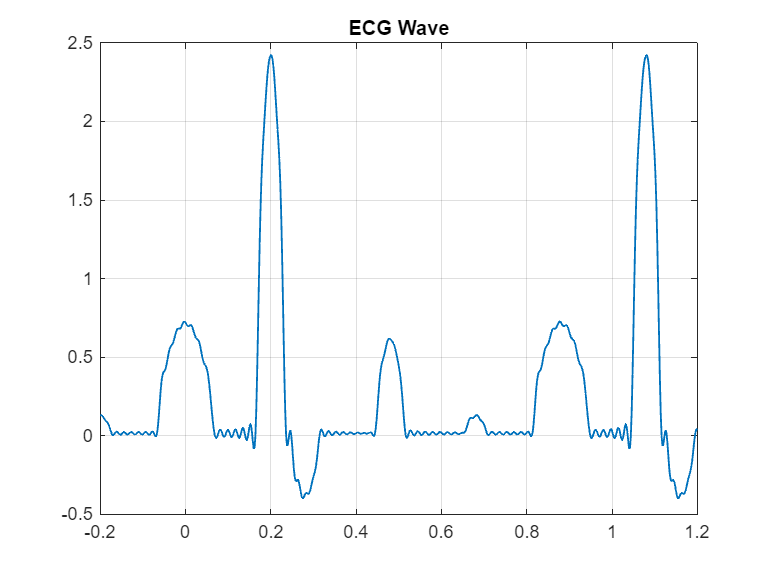

ECG = xtNp + xtNq + xtNs + xtNt + xtNu;
figure; plot(t,ECG, 'linewidth',1)
title ("ECG Wave");
grid on;